clear;
load("data2.mat");
load("game_victor.mat");
m_exc=each_game(data);

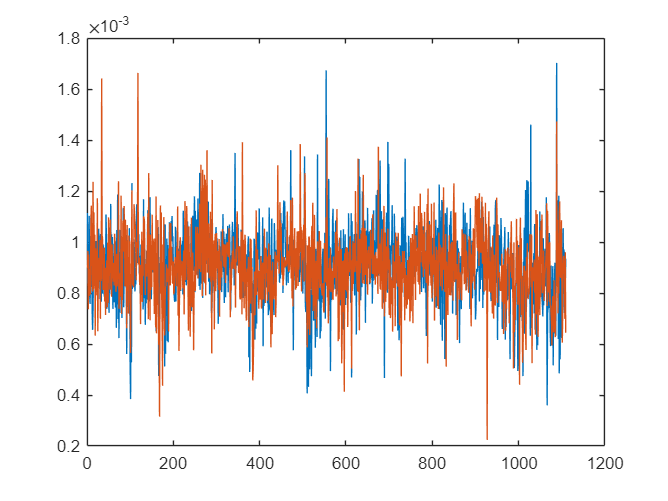

res1=AHPTOPSIS4(m_exc,1);
res2=AHPTOPSIS4(m_exc,2);
x=1:1:1109;
plot(x,res1,x,res2)

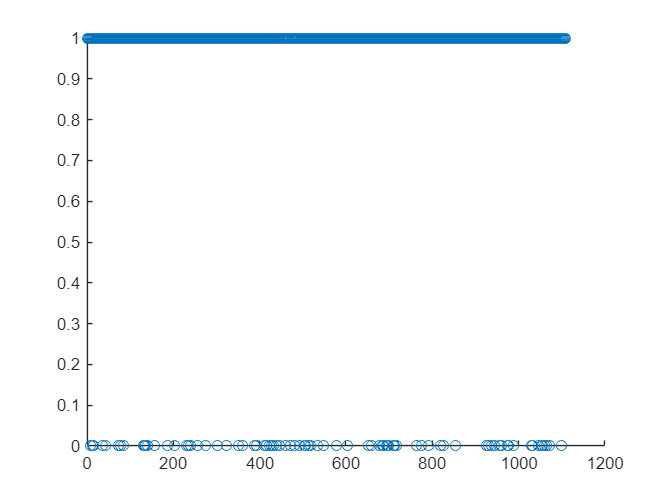

diff=res1-res2;
corrcet=[];
for i=1:length(diff)
    if diff(i)*(data_cut2{i,3}-1.5)<0
        corrcet(i)=1;
    else
        corrcet(i)=0;
    end
end
scatter(1:1:1109,corrcet)

c=sum(corrcet)/1109

c = 0.9261

r=corr(diff,data_cut2{:,3})

r = -0.7576

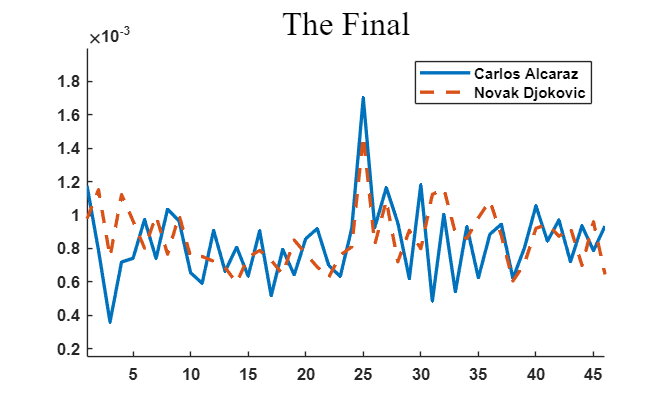

resf1=res1(1109-46+1:1109);
resf2=res2(1109-46+1:1109);
x=1:1:46;
plot(x,resf1,'-',x,resf2,'--',LineWidth=2)
xlim([1,46]);
ylim([0.00015,0.002]);
set(gcf, 'Position', [100, 100, 1000, 600]);
legend('Carlos Alcaraz','Novak Djokovic');
title('The Final','FontName','Times New Roman',FontSize=20);
set(gca,'FontWeight','bold');
box off;

diff=resf1-resf2;
corrcet=[];
for i=1:46
    if diff(i)*(data_cut2{i+1109-46,3}-1.5)<0
        corrcet(i)=1;
    else
        corrcet(i)=0;
    end
end
c=sum(corrcet)/46

c = 0.9348

r=corr(diff,data_cut2{1109-46+1:1109,3})

r = -0.7973